clear All
clc

## Importing variety of time series

Importing S&P 500 Daily time series

spx_short = readmatrix('../data/spx_daily_11-21.csv');
spx_short = fliplr(transpose(spx_short(:,2)));
idx = 1:length(spx_short);
disp("S&P 500 Daily: (length: "+length(spx_short)+")")

S&P 500 Daily: (length: 2560)


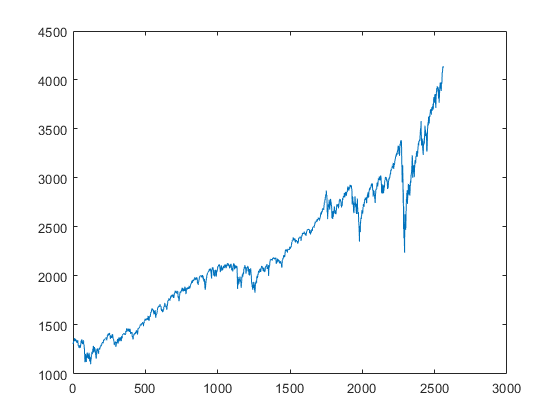

plot(idx,spx_short)

Importing S&P 500 all time Monthly time series over 200 years

spx_long = readmatrix('../data/spx_monthly_alltime.csv');
spx_long = transpose(spx_long(:,2));
idx = 1:length(spx_long);
disp("S&P 500 all time: (length: "+length(spx_long)+")")

S&P 500 all time: (length: 1768)


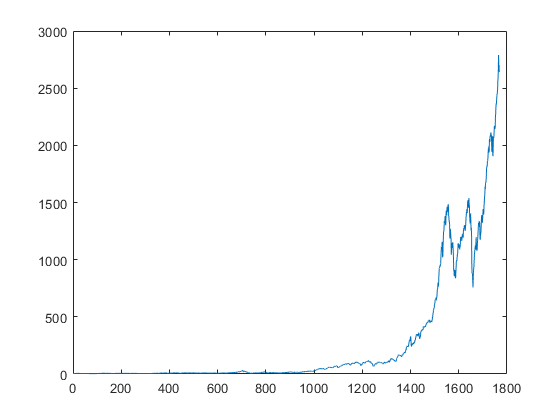

plot(idx,spx_long)

Importing minimum temperature dataset

min_daily_temp = readmatrix('../data/daily-minimum-temperatures-in-melbourne.csv');
min_daily_temp = transpose(min_daily_temp(:,2));
idx = 1:length(min_daily_temp);
disp("Minimum temperature dataset: (length: "+length(min_daily_temp)+")")

Minimum temperature dataset: (length: 3650)


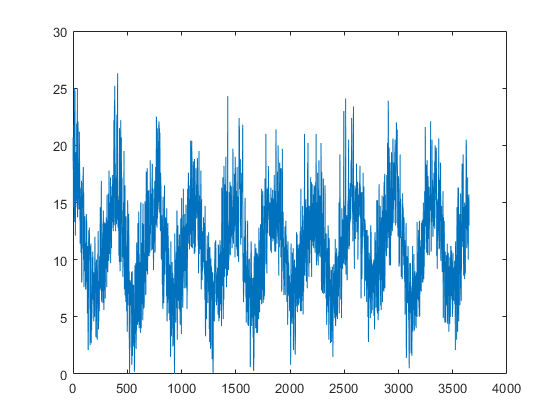

plot(idx,min_daily_temp)

Importing german GDP

bip_de = readmatrix('../data/bip_de_preisbereinigt.csv');
bip_de = transpose(bip_de(:,2));
idx = 1:length(bip_de);
disp("German GDP: (length: "+length(bip_de)+")")

German GDP: (length: 71)


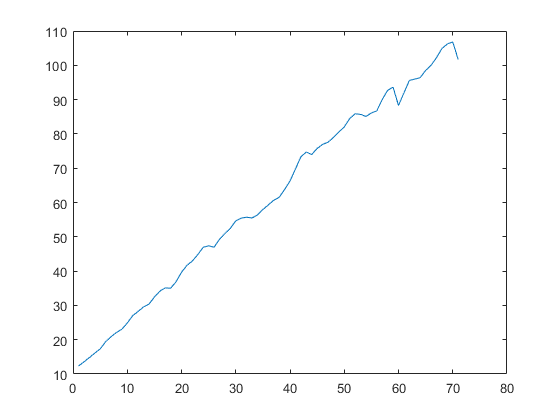

plot(idx,bip_de)

Importing german DAX 2021

dax = readmatrix('../data/dax.csv');
dax = transpose(dax(:,2));
idx = 1:length(dax);
disp("DAX 2021: (length: "+length(dax)+")")

DAX 2021: (length: 254)


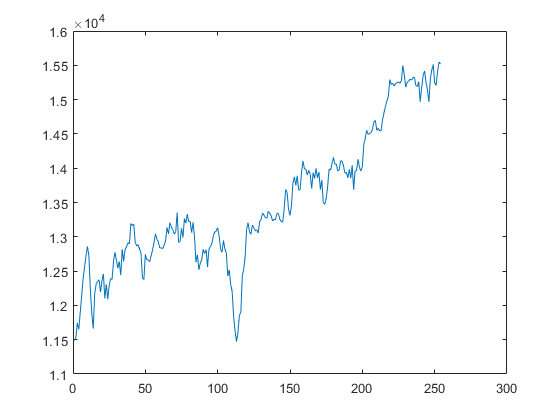

plot(idx,dax)

Importing german DAX alltime

dax_alltime = readmatrix('../data/dax_alltime.csv');
dax_alltime = transpose(dax_alltime(:,2));
idx = 1:length(dax_alltime);
disp("DAX all time: (length: "+length(dax_alltime)+")")

DAX all time: (length: 8602)


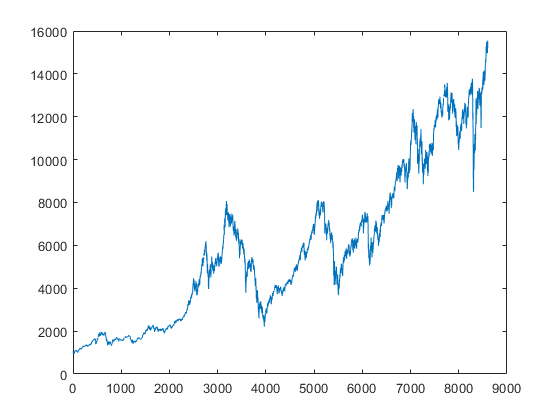

plot(idx,dax_alltime)

Importing Bitcoin alltime

bitcoin_alltime = readmatrix('../data/bitcoin_alltime.csv');
bitcoin_alltime = transpose(bitcoin_alltime(:,2));
for i=2:length(bitcoin_alltime)
    if isnan(bitcoin_alltime(i))
        bitcoin_alltime(i) = bitcoin_alltime(i-1);
    end
end
idx = 1:length(bitcoin_alltime);
disp("Bitcoin all time: (length: "+length(bitcoin_alltime)+")")

Bitcoin all time: (length: 2444)


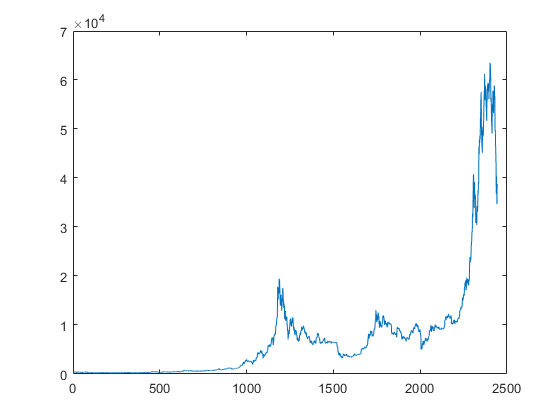

plot(idx,bitcoin_alltime)

Importing hydraulic pressure Data Set

hydraulic = readmatrix('../data/PS1.csv');
hydraulic = transpose(hydraulic(2:length(hydraulic),2));
for i=2:length(hydraulic)
    if isnan(hydraulic(i))
        hydraulic(i) = hydraulic(i-1);
    end
end
idx = 1:length(hydraulic);
disp("Hydraulic pressure data set: (length: "+length(hydraulic)+")")

Hydraulic pressure data set: (length: 6000)


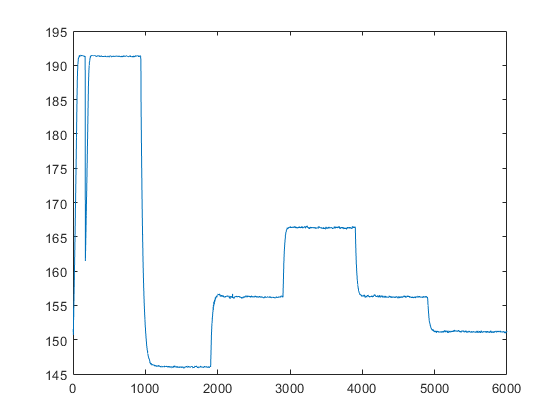

plot(idx,hydraulic)

Importing Beijing O3 in air concentration (quality)

quality = readmatrix('../data/PRSA_Data_Dingling_20130301-20170228.csv');
quality = transpose(quality(:,11));
for i=2:length(quality)
    if isnan(quality(i))
        quality(i) = quality(i-1);
    end
end
idx = 1:length(quality);
disp("Beijing O3 in air concentration : (length: "+length(quality)+")")

Beijing O3 in air concentration : (length: 35064)


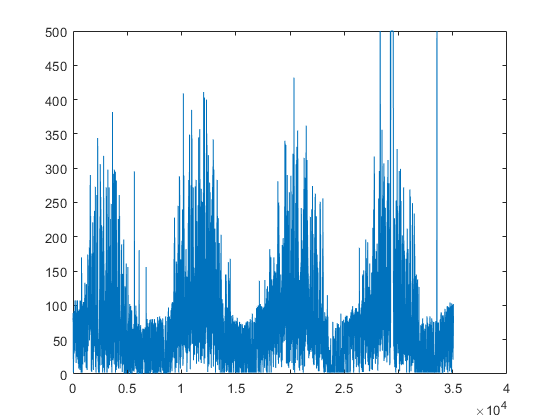

plot(idx,quality)

## Setting hyper parameters for experiment run

% number of iterations of meaningfulness calculation to average over.
n = 1;
% size of cluster set to be calculated for within/between set cluster distance.
r = 3;

ks = [3 5 7 11];
ws = [8 16 32];

normMethods = ["none" "zscore" "norm" "scale" "range" "medianiqr"];
distMetrics = ["eukl" ""];
clusterAlgos = ["kmeans" "agglo" "gmm"];
% timeSeries = [spx_short spx_long min_daily_temp bip_de dax dax_alltime bitcoin_alltime quality hydraulic]

currentNorm = normMethods(1);
% used clustering algorithm
currentClusterAlgo = clusterAlgos(3);

% used distance metric
currentDistMetric = distMetrics(1);

% reduces de sampling size of the random sampled subsequences that are used for whole clustering
% if false the random samples matrix has the same height as the sts matrix
reducedSamplingSize = true;
dimRed = false;

% used time series
currentTs = spx_long;
% Instead of a random walk we could also pass any opposing time series
%opposingTs = spx_long;
opposingTs = createRandomWalk(currentTs);

## Finally calculate Meaningfulness

disp('Experiment settings:')

Experiment settings:


disp('')
fprintf("n:                                           %d",n)

n:                                           1

fprintf('r:                                           %d',r)

r:                                           3

disp('Normalizer:                                  '+currentNorm)

Normalizer:                                  none


disp('Distance metric:                             '+currentDistMetric)

Distance metric:                             eukl


disp('Clustering algorithm:                        '+currentClusterAlgo)

Clustering algorithm:                        gmm


fprintf('Reduced sampling size for whole clustering:  %d',reducedSamplingSize)

Reduced sampling size for whole clustering:  1

fprintf('PCA:                                         %d',dimRed)

PCA:                                         0


figure
title("Target time series - (length: "+length(currentTs)+")")
plot(1:length(currentTs),currentTs)

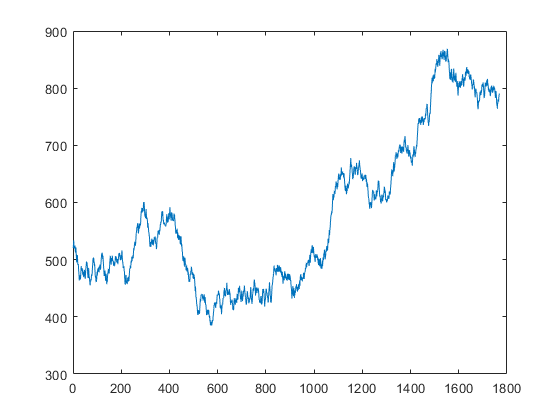

figure
title("Opposing time series - (length: "+length(opposingTs)+")")
plot(1:length(opposingTs),opposingTs)


disp("Results:")

Results:



meaningfulness_combined = zeros(length(ks),2);
i = 1;
for w = 1:length(ws)
    for k = 1:length(ks)
        [sts,whole] = calculateMeaningfulness(currentTs,opposingTs,n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed);
        meaningfulness_combined(k,:,w) = [sts whole];
        i = i+1;
        disp("w="+ws(w)+", k="+ks(k)+" -- STS-meaning: "+sts+", Whole-meaning: "+whole+"");
    end
end

w=8, k=3 -- STS-meaning: 0.00048583, Whole-meaning: 0.00025654
w=8, k=5 -- STS-meaning: 0.17315, Whole-meaning: 0.0697
w=8, k=7 -- STS-meaning: 0.074598, Whole-meaning: 0.096003
w=8, k=11 -- STS-meaning: 0.067474, Whole-meaning: 0.048378
w=16, k=3 -- STS-meaning: 0.0011381, Whole-meaning: 0.2241
w=16, k=5 -- STS-meaning: 0.22443, Whole-meaning: 0.13591
w=16, k=7 -- STS-meaning: 0.098049, Whole-meaning: 0.13038
w=16, k=11 -- STS-meaning: 0.09397, Whole-meaning: 0.04505
w=32, k=3 -- STS-meaning: 0.00070329, Whole-meaning: 0.092408
w=32, k=5 -- STS-meaning: 0.23756, Whole-meaning: 0.035967
w=32, k=7 -- STS-meaning: 0.095071, Whole-meaning: 0.025529
w=32, k=11 -- STS-meaning: 0.087759, Whole-meaning: 0.023547


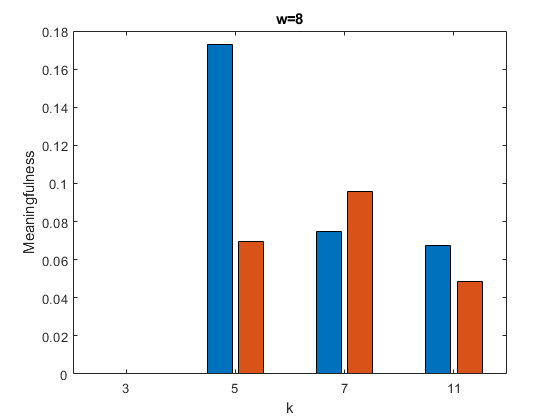

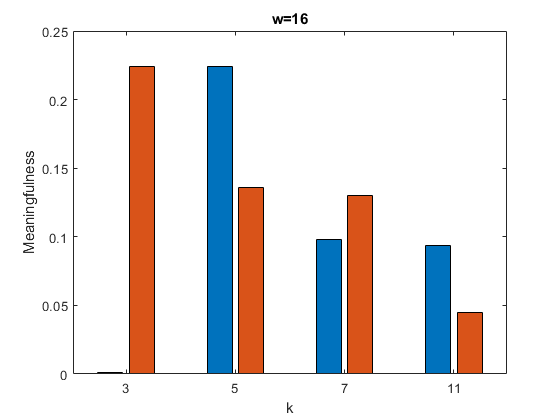

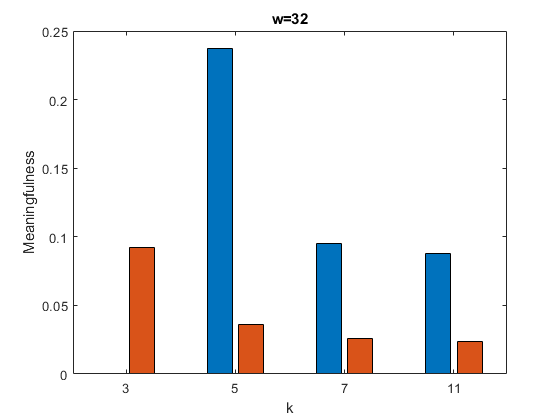


for w = 1:length(ws)
    bar(1:length(ks),meaningfulness_combined(:,:,w))
    set(gca,'XTickLabel',{'3', '5', '7', '11'})
    title("w="+ws(w))
    xlabel('k')
    ylabel('Meaningfulness')
    figure
end